## Lab3.8

(a)定义向量a1,b1,a2,b2以描述系统1,2

a1 = [1 -0.8];
b1 = [1];
a2 = [1 0.8];
b2 = [1];

(b)用freqz计算两个系统频率响应并画图,画出频率响应模值的图像,并判断是哪一种滤波器。

[H1 w1] = freqz(b1,a1,1024,'whole')
[H2 w2] = freqz(b2,a2,1024,'whole')
figure;
%绘制系统1的频率响应
subplot(2,1,1);
plot(w1,abs(H1))
set(gca,'XTick',0:pi/2:2*pi);
set(gca,'XTicklabel',{'0','pi/2','pi','3pi/2','2pi'});
xlabel('w');
ylabel('H1[w]');
%绘制系统2的频率响应
subplot(2,1,2);
plot(w2,abs(H2));
set(gca,'XTick',0:pi/2:2*pi);
set(gca,'XTicklabel',{'0','pi/2','pi','3pi/2','2pi'});
xlabel('w');
ylabel('H2[w]');

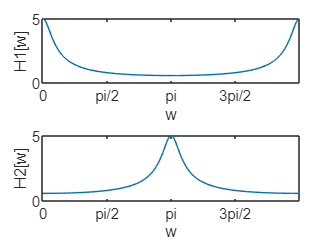

结论：系统1是低通滤波器，系统2是低通滤波器。

(c)定义傅里叶级数的系数，绘制x轴为wk=(2pi/20)k的傅里叶级数系数图

a_x = [0 3/4 0 0 0 0 0 0 0 -0.5 0 -0.5 0 0 0 0 0 0 0 0.75]
wk = [2*pi/20*[0:19]]
figure;
stem(wk,a_x)
set(gca,'XTick',0:pi/10:2*pi);
set(gca,'XTicklabel',{'0','pi/2','pi','3pi/2','2pi'});
xlabel('w_k');
ylabel('a_x');

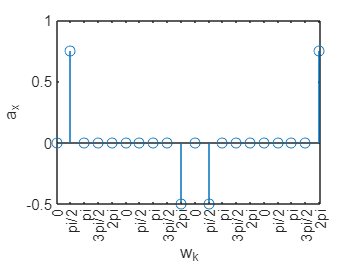

结论：输入信号进入系统1时，a1和a20对应分量将会被放大，a9和a11对于分量将会衰减。输入信号进入系统2时，a9和a11对应分量将会被放大，a1和a20对于分量将会衰减。

(d)由a_k逆傅里叶级数求得x_20，并依此画x。

x_20 = 20*ifft(a_x);
n = -20:99;
x = [x_20 x_20 x_20 x_20 x_20 x_20];
figure;
stem(n,x )
xlabel('n');
ylabel('x');

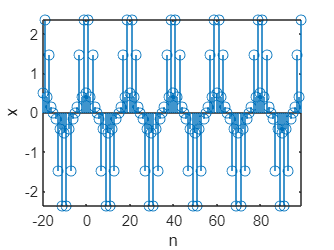

（e)使用filter函数求解x为输入时的y1,y2。绘图，从图中说明哪个系统的输出具有更高的高频能量，哪个有更高的低频能量。

y1 = filter(b1,a1,x)
y2 = filter(b2,a2,x);
n = 0:99;
figure;
%绘制y1
subplot(2,1,1);
plot(n,y1(1,20:119));
xlabel('n');
ylabel('y_1[n]');
%绘制y2
subplot(2,1,2);
plot(n,y2(1,20:119));
xlabel('n');
ylabel('y_2[n]');

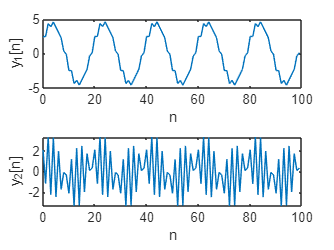

结论：系统1低频能量大，系统2高频能量大，与(c)结论一致。

(f)用fft求y1,y2的傅里叶级数的系数，画出比较高通和低通。

y1_20 = y1(1,20:39);
y2_20 = y2(1,20:39);
a_y1 = fft(y1_20)/20
a_y2 = fft(y2_20)/20;
%绘制y1的傅里叶级数系数
figure;
subplot(2,1,1);
stem(0:pi/10:2*pi-pi/10,a_y1);
set(gca,'XTick',0:pi/10:2*pi);
set(gca,'XTicklabel',{'0','pi/2','pi','3pi/2','2pi'});
ylabel('a_y1');
%绘制y2的傅里叶级数系数
subplot(2,1,2);
stem(0:pi/10:2*pi-pi/10,a_y2);
set(gca,'XTick',0:pi/10:2*pi);
set(gca,'XTicklabel',{'0','pi/2','pi','3pi/2','2pi'});
ylabel('a_y2');

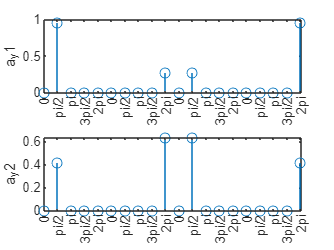

结论：a_y1表明系统1为低通，a_y2表明系统2为高通，与先前结论相符。